close("all"); clear; clc;
setmadsympath();

## Parameters

bs = bigSportsParameters;
s2m = @(x)cell2mat(struct2cell(x));
disp(bikeSimToPrydeParameters(bs,30/3.6));

    Cdelta: 12.6738
      Ibxx: 18.7868
      Ibxz: -1.6611
      Ibzz: 31.7736
      Ihxx: 1.8204
      Ihzz: 0.6908
     kmzaf: 0.9317
     kmzar: 1.0502
     kmzlf: -0.1038
     kmzlr: -0.1498
         v: 8.3333
     kfyaf: 16.6897
     kfyar: 13.4291
     kfylf: -0.6968
     kfylr: -0.4551
        Zf: 1100
        Zr: 1600
         a: 0.7525
        an: 0.0882
         b: 0.6429
         e: 0.0253
         f: 0.2344
         g: 9.8066
         h: 0.5750
       ify: 0.4840
       iry: 0.6380
       kkf: 0
       kkr: 0
        mb: 257.0600
        mh: 24.2400
        rf: 0.2320
        rr: 0.2270
        tf: 0.0500
        tr: 0.0700
    caster: 0.4189



params = @(v)s2m(bikeSimToPrydeParameters(bs,v/3.6));

## Model

nv = 1000;
vx = linspace(30,130,nv);
plant = @prydeMotorcycleLateralStateSpace;
f = @(v)plant(params(v));
sys = arrayfun(f,vx.',"uniform",0);

## Nyquist plot

poles = cellfun(@pole,sys,"uniform",0);
poles = cell2mat(poles);

Plot poles over speed :

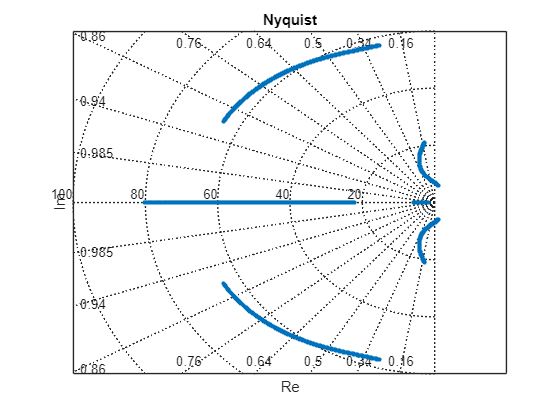

fig = figure();
axe = axes(fig);

scatter(axe,real(poles),imag(poles), ...
    10, ...
    "filled" ...
    );

xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

## BikeSim results

vx = 130;
n2s = @num2str;
results_path = "G:\My Drive\BikeSimResults\BigSports\Chicane";
speed_path = "\Vx" + n2s(vx) + "Kph\";
file_name = "bikesim_results_" + n2s(vx) + "kph.csv";
results = readtable(results_path + speed_path + file_name);

time = results.Time;
camber = results.Roll;
steer = results.Steer;
wz = results.AVz;
vy = results.VyW0_2./3.6;
wx = results.AVx;
ws = -results.M_StrSys./0.2212;

s = (180/pi).*[1,1,1,0,1,1] + [0,0,0,1,0,0];
x_mes = [camber,steer,wz,vy,wx,ws];

Mz = results.M_Str_In;

## Model results

p = params(vx);
sys = plant(p);
sf = (pi/180).*[1,1,1,0,1,1] + [0,0,0,1,0,0];
IC = sf.*x_mes(1,:);
x_sys = s.*lsim(sys,[0.*Mz,Mz],time,IC);

## Kalman filter

% fu = @(t)[0,interp1(time,Mz,t)].';
% d = pi/180;
% sk = (pi/180).*[1,1,0,1] + [0,0,1,0];
% fz = @(t)interp1(time,sk.*x_mes(:,[1,3,4,5]),t).';
% odefun = @(t,x0)kf(t,x0,sys,fu,fz);
% 
% x0 = IC.';
% P0 = eye(6);
% 
% [~,xkf] = ode45(odefun,time,[x0;P0(:)]);
% xkf = s.*xkf(:,1:6);

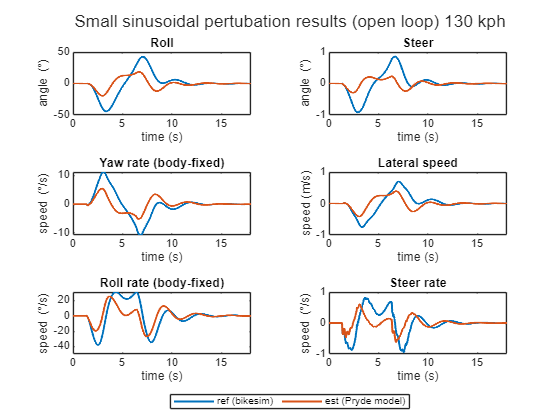

fig = figure();
tl = tiledlayout(3,2,"Parent",fig);

titles = [
    "Roll";
    "Steer";
    "Yaw rate (body-fixed)";
    "Lateral speed";
    "Roll rate (body-fixed)";
    "Steer rate"
    ];

units = [
    "angle (\circ)";
    "angle (\circ)";
    "speed (\circ/s)";
    "speed (m/s)";
    "speed (\circ/s)";
    "speed (\circ/s)"
    ];

for k = 1:6
    axe = nexttile(k);
    hold(axe,"on");
    plot(axe,time,x_mes(:,k),"LineWidth",1.5);
    plot(axe,time,x_sys(:,k),"LineWidth",1.5);
    % plot(axe,time,xkf(:,k),"LineWidth",1.5);
    hold(axe,"off");
    xlim(axe,[0,time(end)]);
    box(axe,"on");
    title(axe,titles(k));
    xlabel(axe,"time (s)");
    ylabel(axe,units(k));
end

ttl = "Small sinusoidal pertubation results (open loop) ";
sgtitle(ttl + vx + " kph");
leg = legend("ref (bikesim)","est (Pryde model)");
% leg = legend("ref (bikesim)","est (Pryde model)","kalman");
leg.Orientation = "horizontal";
leg.Layout.Tile = 'south';

% function dxdt = kf(t,x0,sys,fu,fz)
%     A = sys.A;
%     B = sys.B;
% 
%     H = [
%         1,0,0,0,0,0;
%         0,0,1,0,0,0;
%         0,0,0,1,0,0;
%         0,0,0,0,1,0
%         ];
% 
%     Q = 100.*eye(6);
%     R = eye(size(H,1));
%     x = x0(1:6);
%     P = reshape(x0(7:end),[6,6]);
% 
%     Rinv = R\eye(size(R));
%     K = P*H.'*Rinv;
%     xdot = A*x + B*fu(t) + K*(fz(t) - H*x);
%     Pdot = A*P + P*A.' + Q - P*H.'*Rinv*H*P;
% 
%     dxdt = [
%         xdot;
%         Pdot(:)
%         ];
% end